#### Этап №1

P = [-2.8 -0.2 2.8 -2.1 0.3 -1;
    1.4 -3.5 -4 -2.7 -4.1 -4];
T = [0 1 1 0 1 0];

Обучающее множество (вариант 8)

net = newp([-5 5; -5 5],[0,1]);
display(net);

net =

    Neural Network
 
              name: 'Custom Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 3
        sampleTime: 1
 
    connections:
 
       biasConnect: true
      inputConnect: 

Инициализация сети случайными значениями

net.inputweights{1,1}.initFcn = 'rands';
net.biases{1}.initFcn = 'rands';

net = init(net);

Обучение по правилу Розенблатта (2 эпохи)

epochs=2;
net = rosenblatt_rule(net, P, T, epochs);

IW[1]		IW[2]		b[1]		MAE
3.308564	3.228570	-1.318565	0.500000
3.108564	-0.271430	-0.318565	0.000000


Отображение дискриминантной линии и обучающей выборки

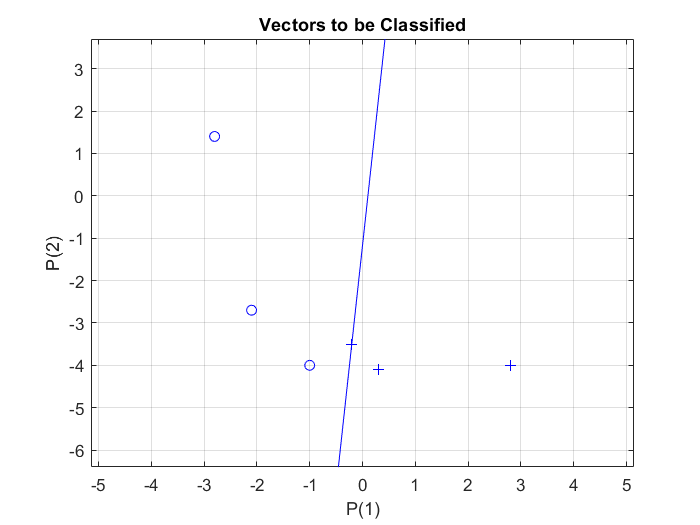

plotpv(P,T), grid
plotpc(net.IW{1},net.b{1})

Повторная инициализация сети случайными значениями. Обучение сети (50 эпох)

net = init(net);
net.trainParam.epochs = 50;
net = train(net, P, T);

Проверка качества обучения

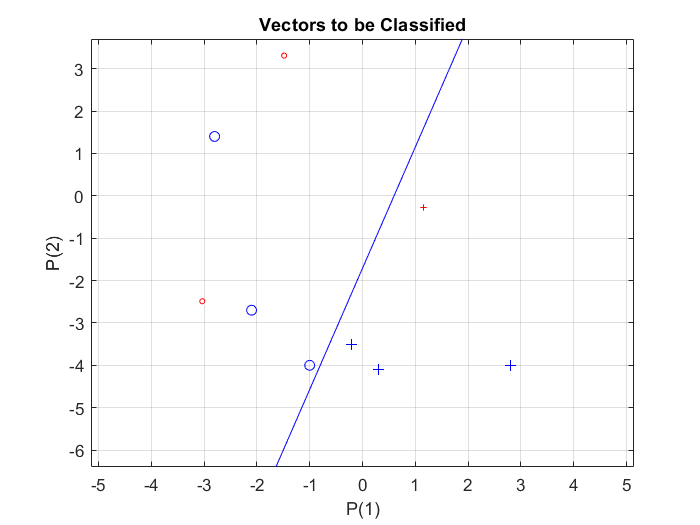

clf;
plotpv(P,T), grid
plotpc(net.IW{1},net.b{1})
sample = 5 * rands(2,3);
hold on
red_color=[1 0 0];
for i=1:size(sample,2)
    s = sample(:,i);
    if net(sample(:,i))
        scatter(s(1), s(2), 10, red_color, '+');
    else
        scatter(s(1), s(2), 10, red_color, 'o');
    end
end
hold off

#### Этап №2

Обучающее множество с линейно неразделимыми классами

P = [-2.8 -0.2 2.8 -2.1 0.3 -1;
    1.4 -3.5 -4 -2.7 -4.1 -4];
T = [0 1 1 0 0 1];

Инициализация случайными значениями

net = init(net);

Обучение сети (50 эпох)

net.trainParam.epochs = 50;
net = train(net, P, T);

Обучающая выборка и дискриминантная линия в случае линейной неразделимости классов

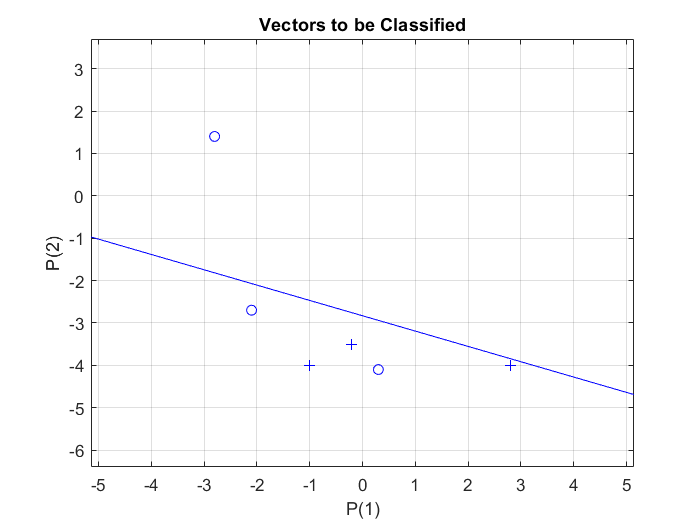

plotpv(P,T), grid
plotpc(net.IW{1},net.b{1})

#### Этап №3

Обучающее множество

P = [1.7  4.7 -0.5  1.8  1.5 -1.3 -3.9  4.7;
    3.3 -4.5  0.8  2.1  2.2  0.8 -4.5 -2.2];
T = [1  0  1  1  1  1  0  0;
    1  1  0  1  1  0  0  1];

Конфигурация сети на 4 класса

net = newp([-5 5; -5 5],[0 1; 0 1]);
display(net);

net =

    Neural Network
 
              name: 'Custom Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 6
        sampleTime: 1
 
    connections:
 
       biasConnect: true
      inputConnect: 

Инициализация случайными значениями. Обучение сети (50 эпох)

net.inputweights{1,1}.initFcn = 'rands';
net.biases{1}.initFcn = 'rands';

net = init(net);

net.trainParam.epochs = 50;
net = train(net, P, T);

Проверка качества обучения

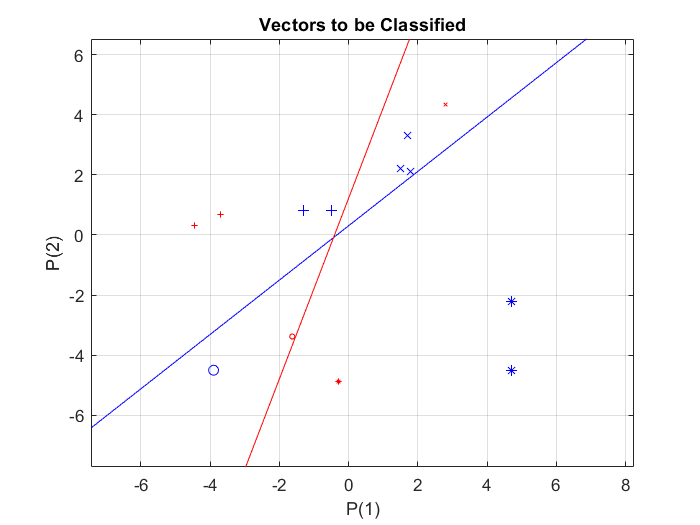

plotpv(P,T), grid
plotpc(net.IW{1},net.b{1})
sample = 5 * rands(2,5);
hold on
red_color=[1 0 0];
for i=1:size(sample,2)
    s = sample(:,i);
    a = net(s);
    if isequal(a, [0; 0])
        scatter(s(1), s(2), 10, red_color, 'o');
    elseif isequal(a, [0; 1])
        scatter(s(1), s(2), 10, red_color, '*');
    elseif isequal(a, [1; 0])
        scatter(s(1), s(2), 10, red_color, '+');
    else
        scatter(s(1), s(2), 10, red_color, 'x');
    end
end
hold off